# Setting-up the study area

We first have to define the sudty area. Here is a toy example with a small island of the French West Indies:

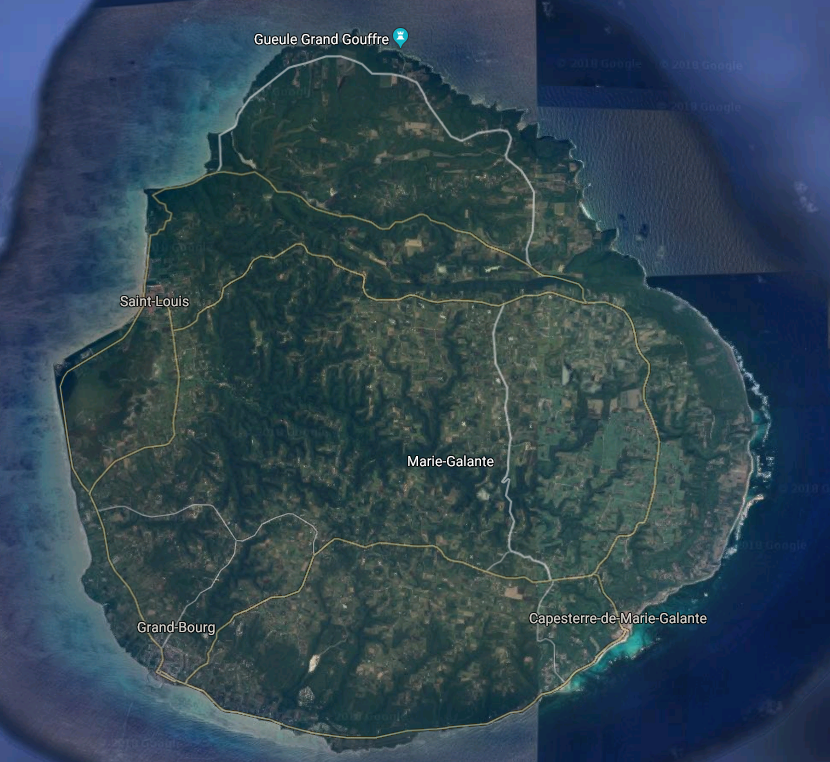

We start by defining a grid on this landscape, producing 36 sites.

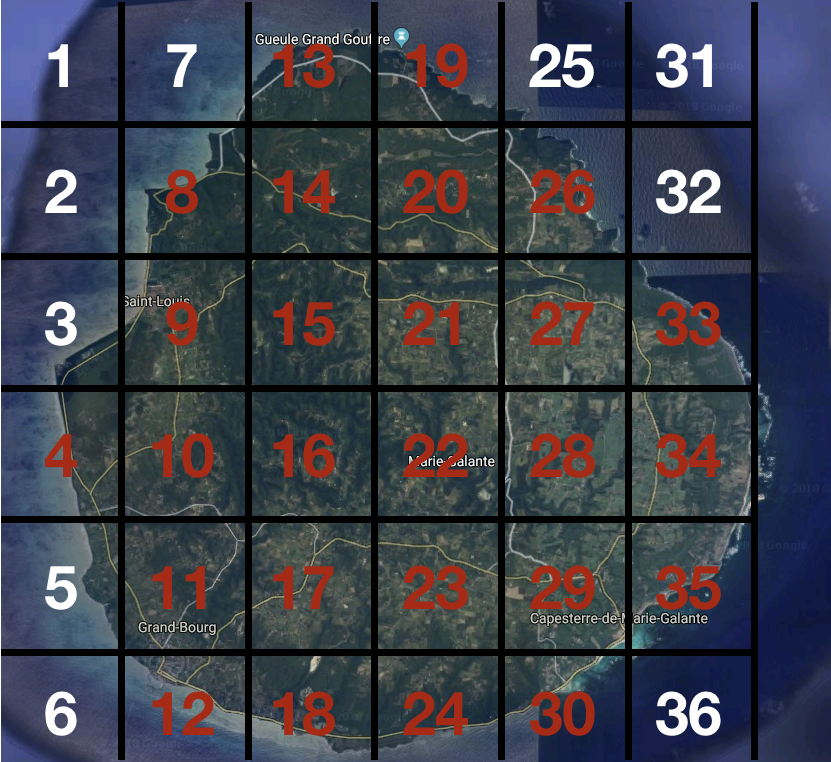

Some sites are red, these are the sites in the study area. 

The white sites are just here to built a rectangular matrix, but will not be considered in the optimisation problem. 

We can now set several variables:

clc
clear all

ligne = 6; % This is the number of rows
colonne = 6; % This is the number of column

% We define the sites that are in the study area
Inside = [4 , 8 , 9 , 10 , 11 , 12 , 13 , 14 , 15 , 16 , 17 , 18 , ...
    19 , 20 , 21 , 22 , 23 , 24 , 26 , 27 , 28 , 29 , 30 , 33 , ...
    34 , 35];

% We also define the vector Outside that can be usefull
Outside = setdiff(1:(ligne*colonne),Inside);

% We set the Zone Number matrix, equals to 1 if ZN(i,j) is inside the study area, 0 otherwise
ZN = zeros(ligne,colonne); 
ZN(Inside) = ones;

# Setting-up the search and destroy cost

It is now necessery to define the cost of searching for the species on-ground. 

Costs have to be rectangular matrix, even if only costs on the Inside sites will be used. Costs on the outside sites can be fixed to any value. 

In this example we use the function *randi *to generate random costs. For a particular application, Search and Destroy matrixes will have to be created by entering the cost associated to each site in the Inside matrix. 

% Cost of searching for the species
Search = randi(50,ligne,colonne);
Search(Outside) = -ones;

% Cost of removing the species
Destroy = randi(50,ligne,colonne);
Destroy(Outside) = -ones;

Finally, the budget have to be define. Here we fixe the budget such that approximately 20% of the sites can be search and destroy

Budget = floor(0.2*(sum(Search(Search >= 0)) + sum(Destroy(Destroy >= 0))));
disp(strcat('The budget is: ',int2str(Budget)))

The budget is:308


# Setting-up the observation

Finally, it is necessary to define the observations. Observations are equal to 1 when the species has been detected and 0 otherwise. 

As for the costs, observations have to be saved in a matrix:

Obs = randi(2,ligne,colonne) - ones;
Obs(Outside) = -ones;

If one want to use the **Grahical User Interface (GUI)**, the observation matrix has to be saved into csv file or it can be created directly by entering the observations in an excel files, respecting the site ordering of the inside matrix. With the GUI, observation have to be of the same length than the Inside vector. They can be created from matlab as follows:

Obs_GUI = Obs(Inside);

csvwrite('Obs.csv',Obs_GUI)

# Define the parameters for the EM algorithm, which estimates the HMRF parameters

Several parameters can be tuned for the parameter estimation algorithm. To use the default values, just ignore the rest of the section and run the following code. To set-up your own parameters, a description of each of them is available just after the code. You can then change any of the parameter value, but do not change matrix sizes, which qill produce a matlab error.

alpha1 = [-0.5 -0.5];
beta1 = 0.5;
Theta1 = [0.1 0.3];
nTest = 5;
max_iter = 1000;
Nit = 30;

- The EM algorithm is an iterative algorithm and an initial value have to be set-up for all the model parameters, $\alpha$, $\beta$ and $\theta$. We used a suffix 1, to state that they are the initial parameters. 

- To improve results, we propose to run the EM algorithl several times. The first time using the initial parameters *alpha1, beta1 *and *Theta1*, and then use the estimated parameters as initial parameters of the next run of the EM algorithm. The vairable *nTest* defines the number of run you want to use. *nTest* should not be set-up to high, in order to reduce computational time. 

- *max_iter *is the maximal number of run of the EM algorithl. It is used to save computational time instead of waiting for convergence. 

- *Nit *is the number of run you want to use for the Gibbs_Sampler algorithm. This algorithm is used to simulate Markov random field value in the EM algorithm.

# Run the EM algorithm

Use the following code to run the EM algorithm

% K is the maximal observation value. We work with presence/absence data here
K = 1; 

% VV is the set of possible observation values
VV = [0 1];

% Initialize several matrix
E = zeros(ligne,colonne);
A = zeros(ligne,colonne);
TrueObs = -ones(ligne,colonne);
MRF = zeros(nTest,2);
Noize = zeros(nTest,2);

% Run the EM algorithm nTest times
h = waitbar(0,'Parameters Estimation');
for i = 1:nTest
    
    close all
    waitbar(i/10,h,['Parameters Estimation ' int2str(i) '/' int2str(nTest) ' ...'])    
    [alpha1,beta1,Theta1,Z1,PI1,PG1,Psi_vec,t,precision] = EM_test(A,Obs,E,alpha1,beta1,Theta1,max_iter,Nit,1,1,TrueObs,ZN);
    MRF(i,1) = alpha1(1);
    MRF(i,2) = beta1;
    Noize(i,:) = Theta1;
    disp(['Current MRF Parameters: $\alpha$  = ' num2str(MRF(i,1)) ', $\beta$ = ' num2str(MRF(i,2))])
    disp(['Current noize Parameters: FP  = ' num2str(Noize(i,1)) ', FN = ' num2str(Noize(i,2))])
end

Current MRF Parameters: $\alpha$  = 2.9, $\beta$ = 1.8769


Current noize Parameters: FP  = 0.71768, FN = 0.50873


Current MRF Parameters: $\alpha$  = 2.8092, $\beta$ = 1.9028


Current noize Parameters: FP  = 0.78153, FN = 0.51431


Current MRF Parameters: $\alpha$  = 2.6872, $\beta$ = 1.8853


Current noize Parameters: FP  = 0.78138, FN = 0.51229


Current MRF Parameters: $\alpha$  = 3.0524, $\beta$ = 2.0526


Current noize Parameters: FP  = 0.8312, FN = 0.51332


Current MRF Parameters: $\alpha$  = 2.933, $\beta$ = 2.0638


Current noize Parameters: FP  = 0.68163, FN = 0.49786


close(h)

% Store the estimated parameter
alpha = zeros(ligne,colonne,2);
alpha(:,:,2) = MRF(end,1);
beta = MRF(end,2);
Theta = Noize(end,:);

% Display the estimated parameters
disp('==== Estimated Parameters ====')

==== Estimated Parameters ====


disp(['\alpha = ' num2str(MRF(end,1))])

\alpha = 2.933


disp(['\beta = ' num2str(MRF(end,2))])

\beta = 2.0638


disp(['\Theta_{FP} = ' num2str(Noize(end,1))])

\Theta_{FP} = 0.68163


disp(['\Theta_{FN} = ' num2str(Noize(end,2))])

\Theta_{FN} = 0.49786


# Compute the marginals

Now we use the belief propagation algorithm to estimate the marginals

[marginals] = Compute_marginals(A,Obs,E,[alpha alpha],beta,Theta,1,ZN,TrueObs);

# Compute the optimal strategy

% We store the indices of the sites inside the study area
I_ZN = find(ZN == 1);

% Define the objective function to be optimize by the LIP algorithm
E_Cost = marginals.*(Search + Destroy) + (ones-marginals).*Search;
f = -1000.*marginals(I_ZN)';
nvars = length(f);
A = E_Cost(I_ZN)';

% Define the option of the LIP problem
lb = zeros(nvars,1);
ub = ones(nvars,1);
intcon = 1:nvars;
Aeq = [];
beq = [];
options = optimoptions('intlinprog','Display','off');

b = Budget;

[x , ~ , ~ , ~] = intlinprog(f,intcon,A,b,Aeq,beq,lb,ub,options);

% The optimal solution x is not necessary a binary vector. We use a thresholding method: 
x(x<0.5) = 0;
x(x>=0.5) = 1;
x_LIP = I_ZN(x == 1);

disp(['Estimated number of searched and occupied cells = ' num2str(sum(marginals(x_LIP)))])

Estimated number of searched and occupied cells = 0.024824


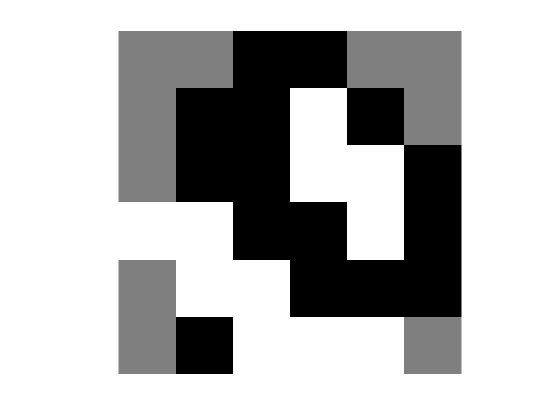



Border = [];
for y = 1:numel(ZN)
    
    if ZN(y) == 0
        x = [(y + 1) , (y - 1) , (y + size(ZN,1)) , (y - size(ZN,1))];
        x = x(x > 0);
        x = x(x <= numel(ZN));
        u = unique(ZN(x));
        if (numel(u) > 1)
            Border = [Border , y];
        end
    end
end

figure('Name','Observation')
title('Observations')
S = Obs;
S(Outside) = 2;
imagesc(S)
axis image
axis off
colormap([1 1 1;1 1 1;0 0 0;.5 .5 .5])

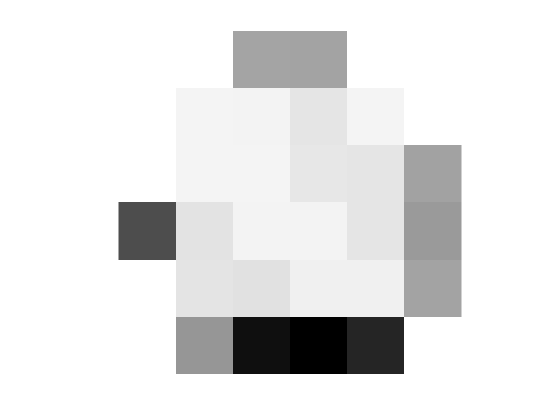


figure('Name','Marginals')
title('Estimated Probability of Presence')
S = marginals;
S(Outside) = zeros;
imagesc(S)
axis image
axis off
colormap(rot90(colormap(gray(1000)),2));

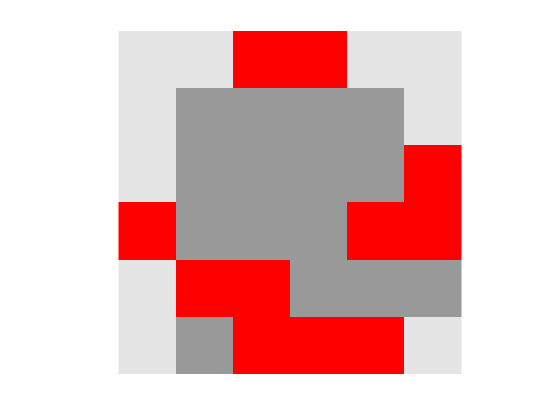


%% Show LIP
S = ZN;
S(x_LIP) = 2;
figure('Name','Where to search')
imagesc(S)
axis image
axis off
colormap([.9 .9 .9;0.6 0.6 0.6;1 0 0])


disp('=======')

disp('Variable to be searched are: ')

Variable to be searched are: 


x_LIP'

ans =      4    11    13    17    18    19    24    28    30    33    34


# Using the Graphical User Interface

If one want to use the **Grahical User Interface (GUI)**, all the input variables should be saved in a xlsx or csv file. The file should not contain headers and with the 1st... 4th columns being the Inside, Observations, Search cost and Sestroy cost variables. Files could be directly created in excel or using matlab as follows:

% Define cost on the inside sites
Search_GUI = Search(Inside)';
Destroy_GUI = Destroy(Inside)';
Obs_GUI = Obs(Inside)';

Data = [Inside' , Obs_GUI , Search_GUI , Destroy_GUI];

% And save input has xlsx files
csvwrite('Data.csv',Data)
